# Heartbeat Monitoring

## Heartbeat Simulation

clear all;
clc;
close all;

disp('Heartbeat Simulation...');

Heartbeat Simulation...



jsonText = fileread('1.json');
data = jsondecode(jsonText);
fsr_signal = double(data.data_PPG);  
fs = 1000;                            % Sampling rate

signal = fsr_signal(1:60*fs);

disp('Data loaded.');

Data loaded.


disp('Simulation starting');

Simulation starting



figure('Position',[150 100 1100 650]);

% Three plots
subplot(3,1,1);
h1 = plot(zeros(1,5000),'b','LineWidth',1.3);
title('Raw FSR Sensor Signal');
ylabel('Amplitude');
grid on;

subplot(3,1,2);
h2 = plot(zeros(1,5000),'g','LineWidth',1.3);
title('Cleaned Signal');
ylabel('Amplitude');
grid on;

subplot(3,1,3);
h3 = plot(0,0,'r','LineWidth',1.5);
title('Heart Rate (BPM)');
ylabel('BPM');
xlabel('Time (seconds)');
grid on;
yline(60,'r--','Bradycardia');
yline(100,'r--','Tachycardia');

sgtitle('Heartbeat Simulation');

% Simulation
disp('Simulation is running...');

Simulation is running...


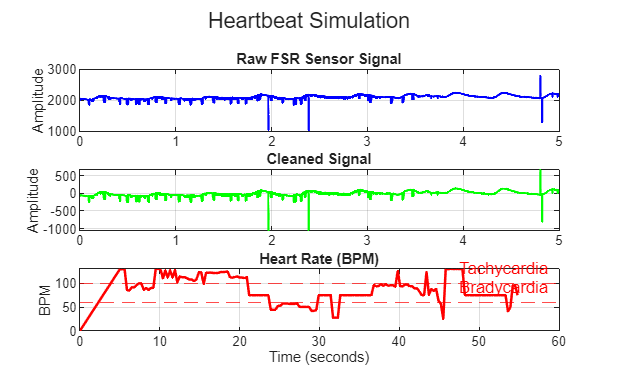


for start = 5000:300:length(signal)-5000
    
    chunk = signal(start:start+5000-1);
    time = (0:4999)/fs;
 
    clean_chunk = chunk - mean(chunk);
 
    [~, peaks] = findpeaks(clean_chunk, 'MinPeakDistance', 450, 'MinPeakHeight', 0.6*max(clean_chunk));
    
    % Calculate heart rate
    if length(peaks) >= 3
        hr = 60 / mean(diff(peaks)/fs);
    else
        hr = 75;   % default value
    end
    
    % Update plots
    set(h1, 'XData', time, 'YData', chunk);
    set(h2, 'XData', time, 'YData', clean_chunk);
    set(h3, 'XData', [get(h3,'XData') start/fs], 'YData', [get(h3,'YData') hr]);
    
    drawnow;
    pause(0.1);   
end


disp('Simulation Finished!');

Simulation Finished!


## Confusion Matrix

%% ===================== MACHINE LEARNING CLASSIFICATION =====================

disp('=== Machine Learning Classification ===');

=== Machine Learning Classification ===



hr_values = get(h3, 'YData');

meanHR = movmean(hr_values, 8);
hr_variation = movstd(hr_values, 8);

features = table(meanHR', hr_variation', 'VariableNames', {'MeanHR', 'HRVariation'});

labels = categorical(strings(length(hr_values),1));
for i = 1:length(hr_values)
    if hr_values(i) < 60
        labels(i) = 'Bradycardia';
    elseif hr_values(i) > 100
        labels(i) = 'Tachycardia';
    else
        labels(i) = 'Normal';
    end
end

model = fitctree(features, labels);
predicted = predict(model, features);

accuracy = sum(predicted == labels) / length(labels) * 100;

% Final Results
final_avg_hr = mean(hr_values(end-30:end));
final_prediction = mode(predicted(end-30:end));

disp('--- Machine Learning Result ---');

--- Machine Learning Result ---


disp(['Average Heart Rate: ', num2str(final_avg_hr), ' BPM']);

Average Heart Rate: 88.6654 BPM


disp(['Heart Rate Variation: ', num2str(mean(hr_variation(end-30:end))), ' BPM']);

Heart Rate Variation: 15.8554 BPM


disp(['ML Predicted Condition: ', char(final_prediction)]);

ML Predicted Condition: Normal


disp(['Model Accuracy: ', num2str(accuracy), '%']);

Model Accuracy: 92.8571%


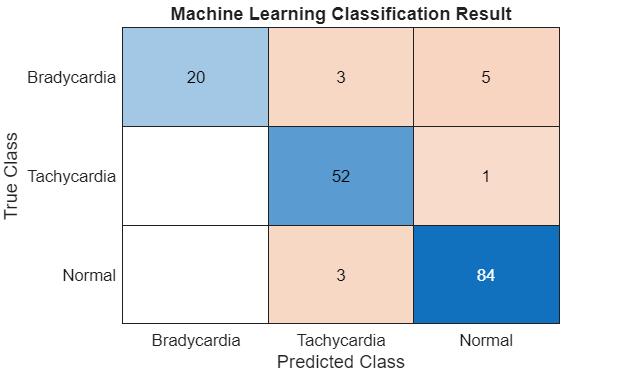


% Confusion matrix
figure;
confusionchart(labels, predicted);
title('Machine Learning Classification Result');


disp(' ');

disp('In the Confusion Matrix:');

In the Confusion Matrix:


disp('→ Darker blue colour = More correct predictions');

→ Darker blue colour = More correct predictions


disp('→ Lighter colour = Fewer or wrong predictions');

→ Lighter colour = Fewer or wrong predictions



disp('Machine Learning Finished!');

Machine Learning Finished!


## Bradycardia and Tachycardia dataset

clear all;
clc;

fs = 1000;
duration = 60;
t = (0:1/fs:duration-1/fs)';

% Normal (~78 BPM)
normal_signal = zeros(length(t),1);
for i = 1:round(fs*60/78):length(t)
    if i+45 <= length(t)
        normal_signal(i:i+45) = 1.8 * sin(linspace(0, 2*pi, 46)).^2;
    end
end
normal_signal = normal_signal + 0.12*randn(size(normal_signal));

% Bradycardia ~33 BPM
brady_signal = zeros(length(t),1);
for i = 1:round(fs*60/33):length(t)
    if i+75 <= length(t)
        brady_signal(i:i+75) = 2.5 * sin(linspace(0, 2*pi, 76)).^2;
    end
end
brady_signal = brady_signal + 0.16*randn(size(brady_signal));

% Tachycardia ~170 BPM
tachy_signal = zeros(length(t),1);
for i = 1:round(fs*60/170):length(t)
    if i+28 <= length(t)
        tachy_signal(i:i+28) = 1.55 * sin(linspace(0, 2*pi, 29)).^2;
    end
end
tachy_signal = tachy_signal + 0.12*randn(size(tachy_signal));

% Save as json file 
writestruct(struct('UID','subject_normal','age',25,'weight',65,'height',175,'data_PPG',normal_signal), '1.json');
writestruct(struct('UID','subject_brady','age',25,'weight',65,'height',175,'data_PPG',brady_signal), 'bradycardia_data.json');
writestruct(struct('UID','subject_tachy','age',25,'weight',65,'height',175,'data_PPG',tachy_signal), 'tachycardia_data.json');

disp('Datasets created successfully');

Datasets created successfully


disp(' -> Bradycardia ~33 BPM');

 -> Bradycardia ~33 BPM


disp(' -> Tachycardia ~170 BPM');

 -> Tachycardia ~170 BPM


## Comparison

%% Load datasets
normal = jsondecode(fileread('1.json'));
brady = jsondecode(fileread('bradycardia_data.json'));
tachy = jsondecode(fileread('tachycardia_data.json'));
sigN = double(normal.data_PPG);
sigB = double(brady.data_PPG);
sigT = double(tachy.data_PPG);
fs = 1000;
%% Function to calculate Heart Rate
calc_hr = @(sig) ...
60 / mean(diff(findpeaks(sig,'MinPeakDistance',400)) / fs);
% Compute HR values
hrN = calc_hr(sigN);
hrB = calc_hr(sigB);
hrT = calc_hr(sigT);
%% ================= TABLE COMPARISON =================
Comparison = table(...
["Normal vs Brady"; "Normal vs Tachy"; "Brady vs Tachy"], ...
[hrN; hrN; hrB], ...
[hrB; hrT; hrT], ...
abs([hrN-hrB; hrN-hrT; hrB-hrT]), ...
'VariableNames', {'Comparison','HR_1 (BPM)','HR_2 (BPM)','Difference (BPM)'});
disp('===== HEART RATE COMPARISON TABLE (BASED ON BPM) =====');

===== HEART RATE COMPARISON TABLE (BASED ON BPM) =====


disp(Comparison);

       Comparison        HR_1 (BPM)     HR_2 (BPM)     Difference (BPM)
    _________________    ___________    ___________    ________________

    "Normal vs Brady"    -2.6054e+06    -2.7949e+06       1.8949e+05   
    "Normal vs Tachy"    -2.6054e+06    -4.0142e+07       3.7536e+07   
    "Brady vs Tachy"     -2.7949e+06    -4.0142e+07       3.7347e+07   



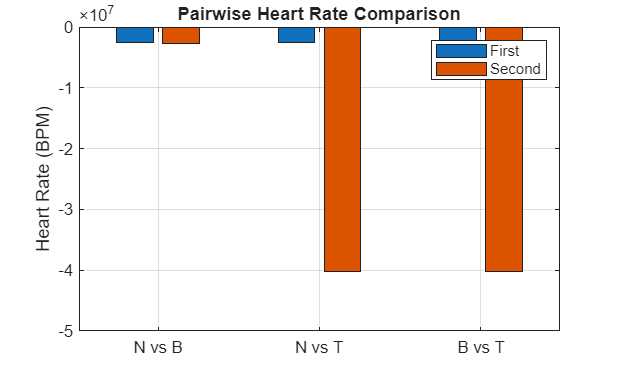

% We are comparing the datasets based on calculated Heart Rate (BPM)
% The table shows BPM values and their differences between Normal, Bradycardia, and Tachycardia signals
%% ================= PAIRWISE GRAPH =================
figure;
bar([hrN hrB; hrN hrT; hrB hrT]);
set(gca,'XTickLabel',{'N vs B','N vs T','B vs T'});
legend('First','Second');
ylabel('Heart Rate (BPM)');
title('Pairwise Heart Rate Comparison');
grid on;

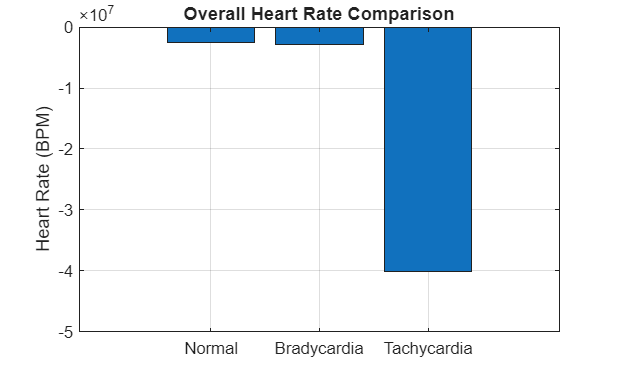

%% ================= OVERALL GRAPH =================
figure;
bar([hrN hrB hrT]);
set(gca,'XTickLabel',{'Normal','Bradycardia','Tachycardia'});
ylabel('Heart Rate (BPM)');
title('Overall Heart Rate Comparison');
grid on;